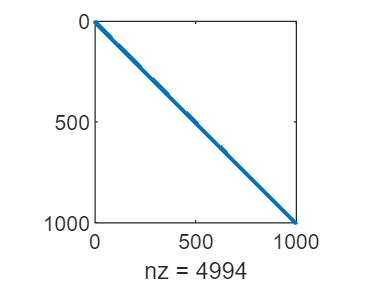

clc,clear,close all
n = 1000;
A1 = diag(1:n);
A2 = diag(ones(1,n-1)*1/2,-1);
A3 = diag(ones(1,n-1)*1/2,1);
A4 = diag(ones(1,n-2)*1/2,-2);
A5 = diag(ones(1,n-2)*1/2,2);
A=A1+A2+A3+A4+A5;

spy(A)

b = A*ones(n,1);

x0 = rand(n,1);
r0 = b-A*x0;
d0 = r0;

%-------共轭梯度法----------%
for k = 0:n-1
    alpha = r0'*r0/(d0'*A*d0);
    x0 = x0+alpha*d0;
    r1 = r0-alpha*A*d0;
    beta = r1'*r1/(r0'*r0);
    d0 = r1+beta*d0;
    r0 = r1;
    if norm(r0,"inf")<1e-6
    break
    end
end
disp('共轭梯度法迭代次数为')

共轭梯度法迭代次数为


disp(k)

   173



disp('误差为')

误差为


disp(norm(x0-ones(n,1),"inf"))

   1.0823e-07




%-------雅克比预条件子共轭梯度法----------%
M = diag(diag(A)); 
x0 = rand(n,1);
r0 = b-A*x0;
z0 = M^(-1)*r0;
d0 = z0;
for k = 0:n-1
    alpha = r0'*z0/(d0'*A*d0);
    x0 = x0+alpha*d0;
    r1 = r0-alpha*A*d0;
    z1 = r0-alpha*A*d0;
    beta = r1'*z1/(r0'*z0);
    d0 = r1+beta*d0;
    r0 = r1;
    z0 = z1;
    if norm(r0,"inf")<1e-6
        k
    break
    end
end

k = 160

disp('雅克比预条件子共轭梯度法迭代次数为')

雅克比预条件子共轭梯度法迭代次数为


disp(k)

   160



disp('误差为')

误差为


disp(norm(x0-ones(n,1),"inf"))

   1.1313e-07




%-------高斯赛德尔预条件子共轭梯度法----------%
D = diag(diag(A));      % 对角线矩阵
U = triu(A,1);         % 上三角矩阵
L = tril(A,-1);        % 下三角矩阵
omega = 0.5;
M = (D+omega*L)*D^(-1)*(D+omega*U); 
x0 = rand(n,1);
r0 = b-A*x0;
z0 = M^(-1)*r0;
d0 = z0;
for k = 0:n-1
    alpha = r0'*z0/(d0'*A*d0);
    x0 = x0+alpha*d0;
    r1 = r0-alpha*A*d0;
    z1 = r0-alpha*A*d0;
    beta = r1'*z1/(r0'*z0);
    d0 = r1+beta*d0;
    r0 = r1;
    z0 = z1;
    if norm(r0,"inf")<1e-6
        k
    break
    end
end

k = 156


disp('高斯赛德尔预条件子共轭梯度法迭代次数为')

高斯赛德尔预条件子共轭梯度法迭代次数为


disp(k)

   156



disp('误差为')

误差为


disp(norm(x0-ones(n,1),"inf"))

   1.0096e-07

